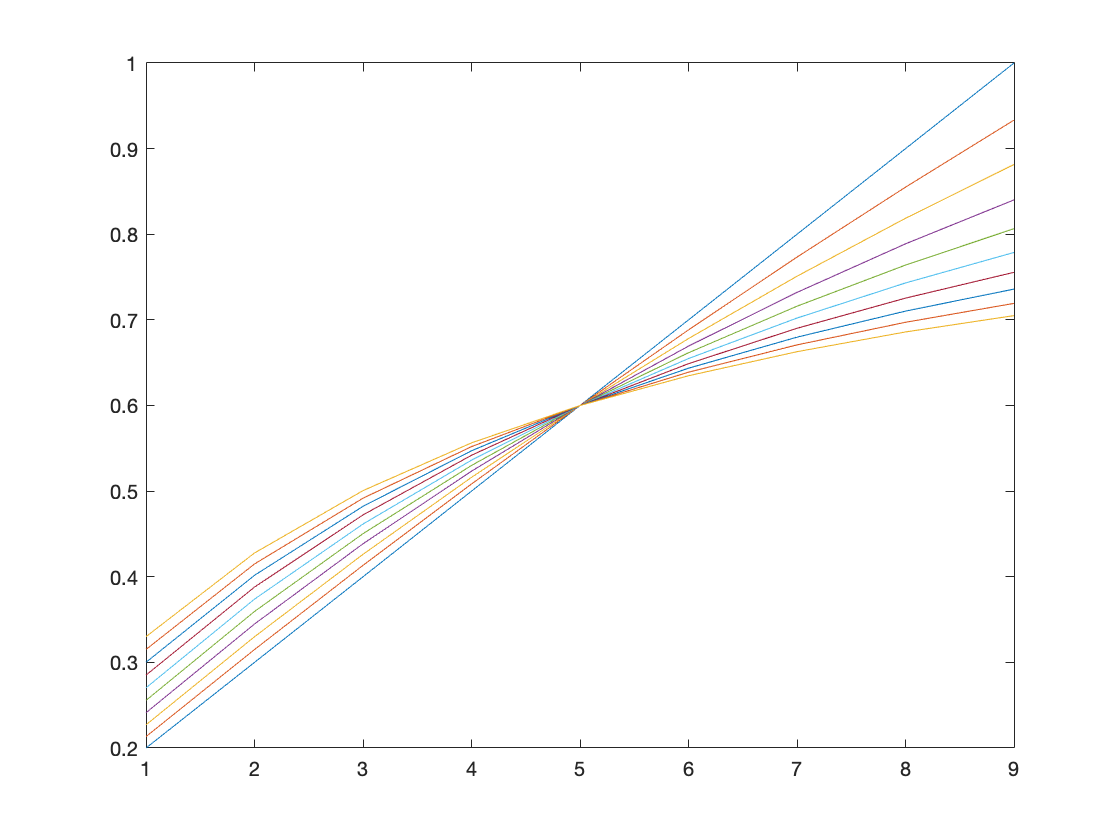

x = [0.2:0.1:1]';
r = 0.1;
K = 0.6;

for start = 1:length(x)
   
    for n = 2:10
    
    x(start,n) = x(start,n-1) + r*(1-x(start,n-1)/K)*x(start,n-1);
    
    end
    
end

plot(x)

x

x =     0.2000    0.2133    0.2271    0.2412    0.2556    0.2703    0.2851    0.3001    0.3151    0.3301
    0.3000    0.3150    0.3300    0.3448    0.3595    0.3739    0.3880    0.4017    0.4150    0.4278
    0.4000    0.4133    0.4262    0.4385    0.4503    0.4616    0.4722    0.4823    0.4917    0.5006
    0.5000    0.5083    0.5161    0.5233    0.5300    0.5362    0.5419    0.5471    0.5520    0.5564
    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000
    0.7000    0.6883    0.6782    0.6694    0.6616    0.6548    0.6488    0.6436    0.6389    0.6347
    0.8000    0.7733    0.7510    0.7321    0.7160    0.7021    0.6902    0.6798    0.6708    0.6629
    0.9000    0.8550    0.8187    0.7888    0.7640    0.7431    0.7254    0.7102    0.6972    0.6859
    1.0000    0.9333    0.8815    0.8401    0.8065    0.7787    0.7555    0.7360    0.7193    0.7050


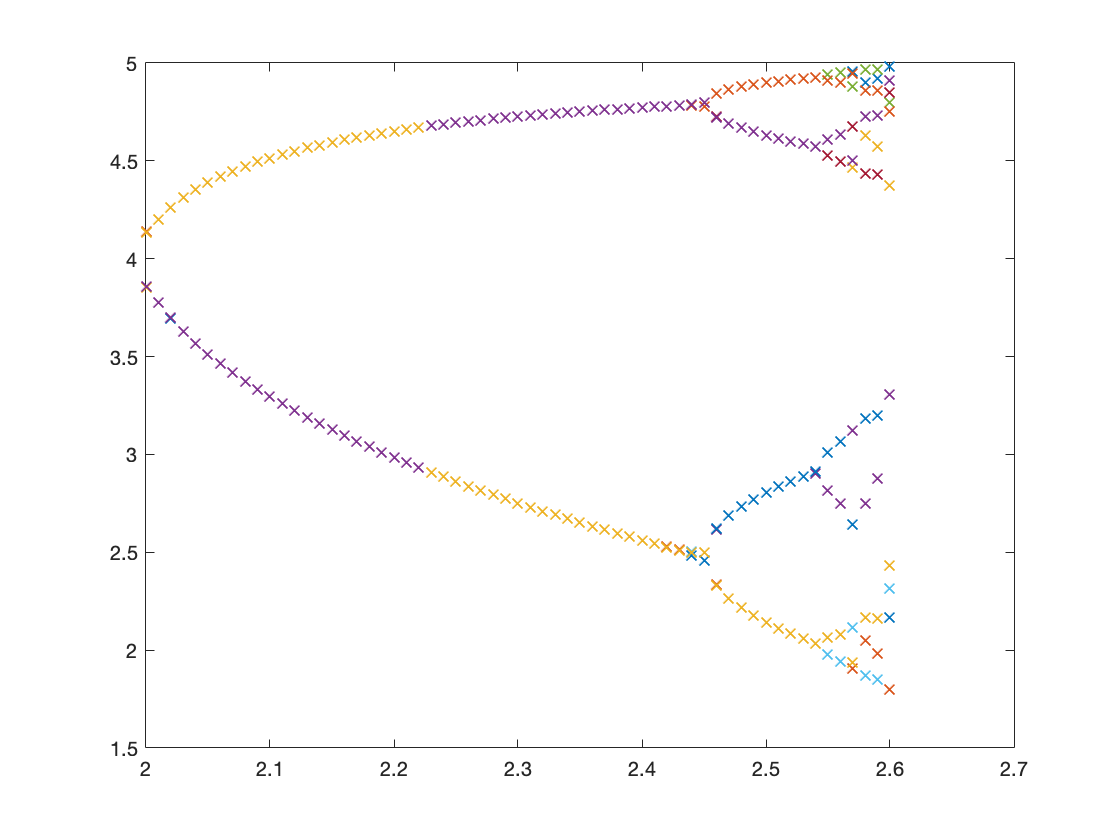

r = 2:0.01:2.6;
x = [0.2]*ones(length(r),1);
K = 4;

for r_row = 1:length(r)
   
    for n = 2:100
    
    x(r_row,n) = x(r_row,n-1) + r(r_row)*(1-x(r_row,n-1)/K)*x(r_row,n-1);
    
    end
    
end

plot(r,x(:,end-10:end),'x')

x

x =     0.2000    0.5800    1.5718    3.4801    4.3847    3.5412    4.3535    3.5840    4.3295    3.6162    4.3101    3.6418    4.2941    3.6627    4.2804    3.6803    4.2686    3.6953    4.2583    3.7084    4.2491    3.7199    4.2409    3.7301    4.2335    3.7393    4.2267    3.7475    4.2206    3.7551    4.2149    3.7620    4.2097    3.7683    4.2048    3.7742    4.2003    3.7796    4.1961    3.7847    4.1921    3.7894    4.1884    3.7938    4.1849    3.7980    4.1816    3.8019    4.1785    3.8056
    0.2000    0.5819    1.5814    3.5033    4.3777    3.5468    4.3545    3.5788    4.3363    3.6036    4.3214    3.6234    4.3091    3.6398    4.2986    3.6536    4.2895    3.6654    4.2817    3.6757    4.2747    3.6846    4.2686    3.6925    4.2631    3.6995    4.2581    3.7058    4.2536    3.7115    4.2495    3.7167    4.2458    3.7213    4.2424    3.7256    4.2393    3.7295    4.2364    3.7331    4.2337    3.7365    4.2313    3.7395    4.2290    3.7424    4.2268    3.7450    4.2248    3